# Ordinary differential equations with MATLAB and the symbolic toolbox

ODEs are a common tool in engineering modelling and system analysis so students need to be competent in solving them. However, in truth, apart from trivial examples, these are somewhat tedious to do on pen and paper. Hence MATLAB provides a file ***dsolve.m*** which will generate the solutions for most examples you are likely to encounter in the year 1 and 2 curriculum. This file largely provides a number of worked examples students can use as exemplars for understanding how the tool works before solving their own problems.

You must have the symbolic toolbox installed for this file to work.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Preliminaries

- Solving 1st order ODEs

- Solving 2nd order ODEs

- Example of a higher order ODE

## **1. Preliminaries**

Let the ODE to be solved be given as:


$$a_n \frac{d^n x}{dt^n }+a_{n-1} \frac{d^{n-1} x}{dt^{n-1} }+a_{n-2} \frac{d^{n-2} x}{dt^{n-2} }+\ldotp \ldotp \ldotp +a_{o\;} x=f\left(t\right)$$


You need to define symbolic variables/functions to capture all the core terms in the ODE, so that is time, the state x and all the derivatives. An example is given here

clear 
syms x(t) t       % for the state and time
Dx = diff(x);     % for first derivative
D2x = diff(Dx);   % for 2nd derivative
D3x = diff(D2x);  % for 3rd derivative
whos

  Name      Size            Bytes  Class     Attributes

  D2x       1x1                 8  symfun              
  D3x       1x1                 8  symfun              
  Dx        1x1                 8  symfun              
  t         1x1                 8  sym                 
  x         1x1                 8  symfun              



## 2. Solving 1st order ODEs

This section gives a number of simple examples from which it is hoped the use of the code is self-evident.  It is particularly important to note the use of "==" in the syntax.


$$a_1 \frac{\textrm{dx}}{\textrm{dt}}+a_{o\;} x=f\left(t\right)$$


**Example 1:  **$6\frac{\textrm{dx}}{\textrm{dt}}+4x=3,\;x\left(0\right)=2$

disp('BELOW is SECTION 2')

BELOW is SECTION 2


syms x(t);  
Dx=diff(x);
xt=dsolve(6*diff(x)+4*x==7,x(0)==2)

$$xt = \frac{{\mathrm{e}}^{-\frac{2\,t}{3}}}{4}+\frac{7}{4}$$

**Example 2: **$0\ldotp 1\frac{\textrm{dy}}{\textrm{dt}}-2\ldotp 1y=0\ldotp 5,y\left(0\right)=-1$

syms y(t)
yt=dsolve(0.1*diff(y)-2.1*y==0.5,y(0)==-1)

$$yt = -\frac{16\,{\mathrm{e}}^{21\,t}}{21}-\frac{5}{21}$$

**Example 3a with illustration of plotting: **$2\frac{\textrm{dz}}{\textrm{dt}}+5z=0,z\left(0\right)=-4$

syms z(t)
zt=dsolve(2*diff(z)+5*z==0,z(0)==-4')

$$zt = -4\,{\mathrm{e}}^{-\frac{5\,t}{2}}$$


% Plotting
t=linspace(0,2,100);
z_values=subs(zt,t)

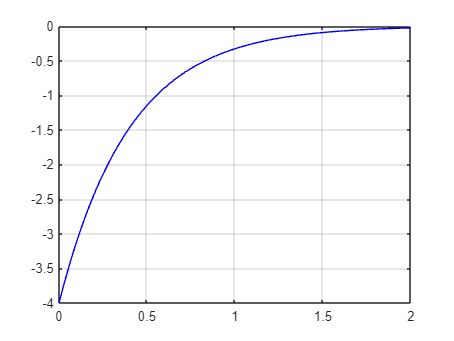

figure;clf reset
plot(t,z_values,'b');grid

**Example 3b with illustration of different right hand side: **$2\frac{\textrm{dz}}{\textrm{dt}}+5z=t+\sin \left(3t\right),z\left(0\right)=-4$

syms z(t) t
zt=dsolve(2*diff(z)+5*z==t+sin(3*t),z(0)==-4')

$$zt = \frac{t}{5}-\frac{5828\,{\mathrm{e}}^{-\frac{5\,t}{2}}}{1525}-\frac{\sqrt{61}\,\cos\left(3\,t+\mathrm{atan}\left(\frac{5}{6}\right)\right)}{61}-\frac{2}{25}$$


%plotting
t=linspace(0,2.5,100);
z_values=subs(zt,t)

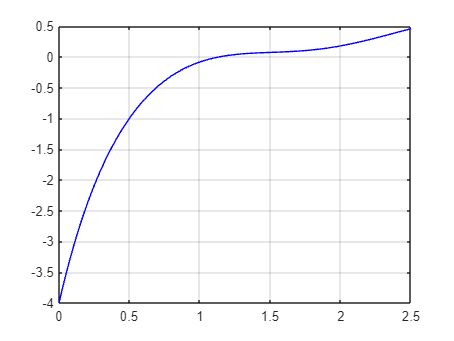

figure;clf reset
plot(t,z_values,'b');grid

### 3. Solving 2nd order ODEs

This section gives a number of simple examples from which it is hoped the use of the code is self-evident.  It is particularly important to note the use of "==" in the syntax.


$$a_2 \frac{d^2 x}{dt^2 }+a_1 \frac{\textrm{dx}}{\textrm{dt}}+a_{o\;} x=f\left(t\right)$$


**Example 1: **$\frac{d^2 y}{dt^2 }+15\frac{\textrm{dy}}{\textrm{dt}}+14y=1,y\left(0\right)=0,\overset{\ldotp }{y} \left(0\right)=0$

disp('BELOW is SECTION 3')

BELOW is SECTION 3


syms y(t)
Dy=diff(y);
D2y=diff(Dy);
yt=dsolve(D2y+15*Dy+14*y==1,y(0)==0, Dy(0)==0)

$$yt = \frac{{\mathrm{e}}^{-14\,t}}{182}-\frac{{\mathrm{e}}^{-t}}{13}+\frac{1}{14}$$

%%

**Example 2 with plotting:  **$\frac{d^2 x}{dt^2 }+40\frac{\textrm{dx}}{\textrm{dt}}+76x=1,\;x\left(0\right)=2,\overset{\ldotp }{x} \left(0\right)=0$


syms x(t)  
Dx=diff(x);
D2x=diff(Dx);
xt=dsolve(D2x+40*Dx+76*x==1,x(0)==0, Dx(0)==0)

$$xt = \frac{{\mathrm{e}}^{-38\,t}}{1368}-\frac{{\mathrm{e}}^{-2\,t}}{72}+\frac{1}{76}$$

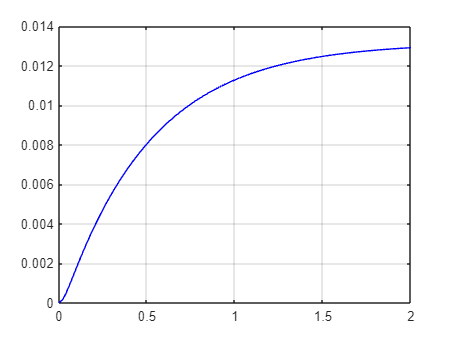


% PLOTTING
t=linspace(0,2,100);
xx=subs(xt,t);
figure(1);clf reset
plot(t,xx,'b');grid

**Example 3 with more complicated forcing function:  **$5\frac{d^2 x}{dt^2 }+20\frac{\textrm{dx}}{\textrm{dt}}+65x=e^{-t} +\sin \left(4t\right),\;x\left(0\right)=2,\overset{\ldotp }{x} \left(0\right)=1$

syms x(t) t 
Dx=diff(x);
D2x=diff(Dx);
xt=dsolve(5*D2x+20*Dx+65*x==exp(-t)+sin(4*t),x(0)==2, Dx(0)==1)

$$xt = \frac{5279\,\cos\left(3\,t\right)\,{\mathrm{e}}^{-2\,t}}{2650}+\frac{2657\,\sin\left(3\,t\right)\,{\mathrm{e}}^{-2\,t}}{1590}+\frac{\cos\left(3\,t\right)\,{\mathrm{e}}^{-t}\,\left(159\,\cos\left(3\,t\right)-53\,\sin\left(3\,t\right)-106\,{\mathrm{e}}^{t}\,\cos\left(t\right)-53\,{\mathrm{e}}^{t}\,\sin\left(t\right)+10\,\cos\left(7\,t\right)\,{\mathrm{e}}^{t}+35\,\sin\left(7\,t\right)\,{\mathrm{e}}^{t}\right)}{7950}+\frac{\sin\left(3\,t\right)\,{\mathrm{e}}^{-t}\,\left(53\,\cos\left(3\,t\right)+159\,\sin\left(3\,t\right)-53\,{\mathrm{e}}^{t}\,\cos\left(t\right)+106\,{\mathrm{e}}^{t}\,\sin\left(t\right)-35\,\cos\left(7\,t\right)\,{\mathrm{e}}^{t}+10\,\sin\left(7\,t\right)\,{\mathrm{e}}^{t}\right)}{7950}$$

## 4. Example of a higher order ODE

You will note that the solutiions become somewhat lengthy and fill the screen.  You can of course use subs.m if ultimately you just want to find the corresponding numerical values.

WARNING: If the solution is too difficult, MATLAB may take a long time, appear to be busy, etc.

**Example with complicated forcing function:  **$\frac{d^3 x}{dt^3 }+6\frac{d^2 x}{dt^2 }+11\frac{\textrm{dx}}{\textrm{dt}}+6x=e^{-t} +\sin \left(4t\right),\;x\left(0\right)=2,\overset{\ldotp }{x} \left(0\right)=1,\overset{\ldotp \ldotp }{x} \left(0\right)=0$

disp('BELOW is SECTION 4')

BELOW is SECTION 4


syms x(t) t 
Dx=diff(x);
D2x=diff(Dx);
D3x = diff(D2x)

$$D3x(t) = \frac{\partial^{3}}{\partial t^{3}}x\left(t\right)$$

xt=dsolve(D3x+6*D2x+11*Dx+6*x==exp(-t)+sin(4*t),x(0)==2, Dx(0)==1,D2x(0)==0)

$$xt = \frac{535\,{\mathrm{e}}^{-t}}{68}-\frac{46\,{\mathrm{e}}^{-2\,t}}{5}+\frac{333\,{\mathrm{e}}^{-3\,t}}{100}+\frac{t\,{\mathrm{e}}^{-t}}{2}+\frac{\sqrt{85}\,\cos\left(4\,t+\mathrm{atan}\left(\frac{9}{2}\right)\right)}{850}$$